# Tutorial02

#### Diary, including review

help xxx

% help hist

In general, the doc command has more depth.

% doc hist  % opens the matlab documentation

Tips

Can copy relevant commands from the **command history** window into a text file or doc.

Can also cut a graph (Edit > Copy figure) then paste it in my diary.

Make a separate document for the assignment.

**Comment**, long and short: on what's going on.

## 1 Plotting a Function

### 1.1 Making Lists of Numbers

To plot a fn, first need to make two lists of #s(vectors). 

% help colon

Refresher

a = 1:5;
b = a + 20;

Recap of tutorial 1

time = 0:0.1:1;

Assign a list of 101 #s ranging from 0 to 1

time = 0:0.1:10;
size(time) % to check size is 101

ans =      1   101


Now, apply a fn to our array.

Will consider the solution to a differential equation.

V(t) = 1−e^(−t/τ)

t: elapsed time

V: measured quantity (activity of an enzyme relative to its max)

τ: tau. A constant that controls how the model behaves. The value is unknown.

Note: **exp** for exponential.

tau = 1;
V = 1-exp(-time/tau)

V =          0    0.0952    0.1813    0.2592    0.3297    0.3935    0.4512    0.5034    0.5507    0.5934    0.6321    0.6671    0.6988    0.7275    0.7534    0.7769    0.7981    0.8173    0.8347    0.8504    0.8647    0.8775    0.8892    0.8997    0.9093    0.9179    0.9257    0.9328    0.9392    0.9450    0.9502    0.9550    0.9592    0.9631    0.9666    0.9698    0.9727    0.9753    0.9776    0.9798    0.9817    0.9834    0.9850    0.9864    0.9877    0.9889    0.9899    0.9909    0.9918    0.9926


To see some built-in fns:

% help elfun

Note: The dot-hat syntax.

e.g. W = t.^2  % To apply squaring operation item-by-item.

### 1.2 The plot Command

What: Evaluate V(t) on some range of values for t.

So far, we have: two lists of #s of the same length, **time** and **V**.

Now, plot.

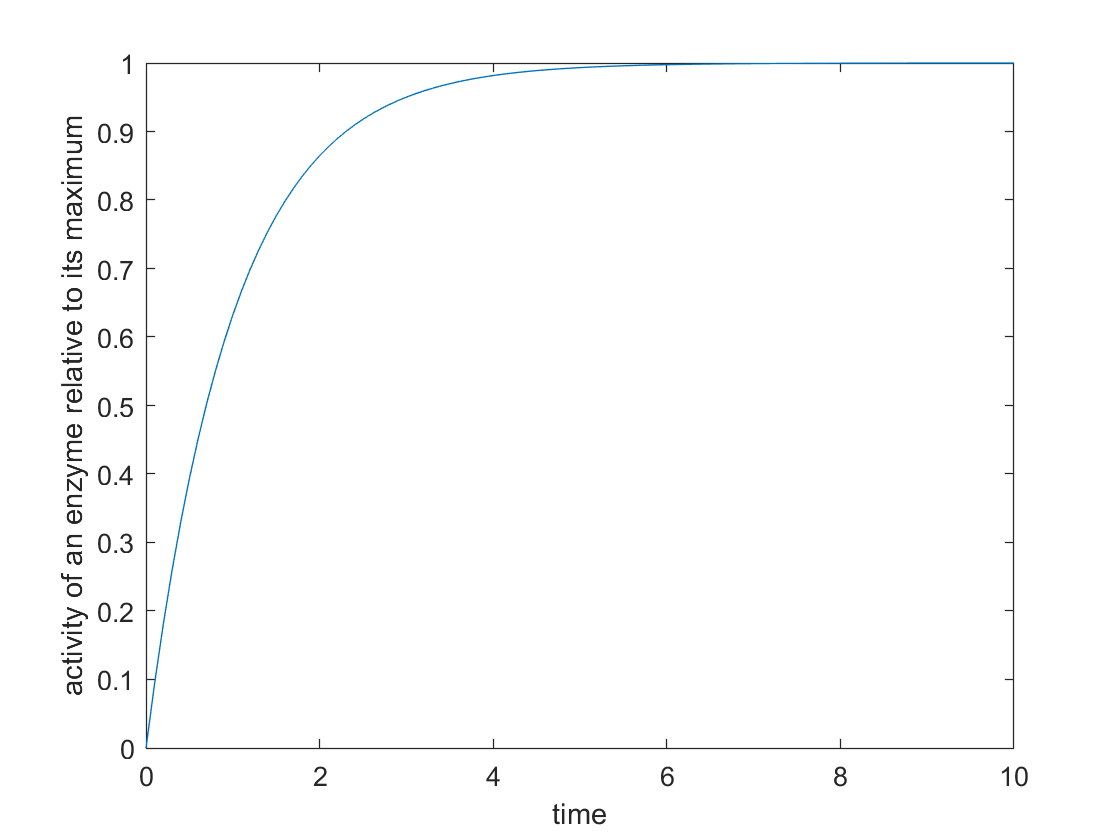

plot(time, V)

xlabel('time')
ylabel('activity of an enzyme relative to its maximum')

To see summary info about variables, double click on a variable. We'll see more details.

MATLAB lets us modify a plot interactively using menus.

Note: how to specify a semilog plot

**semilogy**: the same as plot but log scale (base 10) is used for y-axis.

%help semilogy

Assignment 1.2

>> In a different file.

1.3 The Editor Window

Note: In the tutorial, so far, the command line was used, but I used the editor window instead.

Could possibly do

**edit mycode.m**

on the command prompt.

**Ctrl-N** also works.

% edit tut02_assignment_2.3.mlx

^ Actually created a file for an assignment using the code above.

Interactive mode vs window mode

Interactive mode is often used for making once-only graphs.

Some exercises suggested in this section, but already done previously, as I've been using the window mode.

2. Importing and Manipulating Data

2.1 A word about units

(Recap about comment)

Write comments to increase readability and understanding of the reader. Also for our own sake.

Add **coment** lines to specify the unit being used for each variable.

Example:

% time = time in hours

2.2 Getting the dataset

[http://www.physics.upenn.edu/biophys/Datasets/](http://www.physics.upenn.edu/biophys/Datasets/) is the place to find the list of datasets we may be using in this course.

Note:

The URL seemed to be invalid. Searched up this site[https://www.physics.upenn.edu/biophys/PMLS/Datasets/datasetlist.pdf](https://www.physics.upenn.edu/biophys/PMLS/Datasets/datasetlist.pdf) 

and downloaded [http://www.physics.upenn.edu/biophys/PMLS/Datasets/PMLSdata.zip](http://www.physics.upenn.edu/biophys/PMLS/Datasets/PMLSdata.zip) instead.

Moved the **g149novickA.mat** into my folder.

Now, load the data:

load g149novickA.mat
who  % to check what variables are loaded


Your variables are:

A       V2      a       data    tau2    time    
V       V3      ans     tau     tau3    x_time  
V1      V4      b       tau1    tau4    y_data  



See what's in data.

data

data =     0.1699    0.0190
    0.4426    0.0855
    0.5111    0.1164
    0.7156    0.1639
    1.0564    0.2470
    1.2041    0.2803
    1.4311    0.3278
    1.6465    0.3563
    1.8283    0.4038
    2.1119    0.4537


data contains an array "a bit like a spreadsheet". 

1st col: times at which measurements were taken

2nd col: corresponding values of the measured quantity.

2.3 Fitting the model

BEFORE we can plot the enzyme activity as a fn of t, we need to do a simple manipulation to extract one vector from the first column of **data** variable AND another vec from the second column.

Solution: Use column operator.

x_time = data(:,1) % extract the 1st col of data

x_time =     0.1699
    0.4426
    0.5111
    0.7156
    1.0564
    1.2041
    1.4311
    1.6465
    1.8283
    2.1119


y_data = data(:,2) % extract the 2nd col of data

y_data =     0.0190
    0.0855
    0.1164
    0.1639
    0.2470
    0.2803
    0.3278
    0.3563
    0.4038
    0.4537


Assignment

>> In **tut02_assignment_2.3.mlx**